# Hierarchy of Time Surfaces with one dimension events

## Level-crossing an frame-based signal into an event-based one

Let's consider an audio recording of someone saying 'The emperor had a mean temper.' :

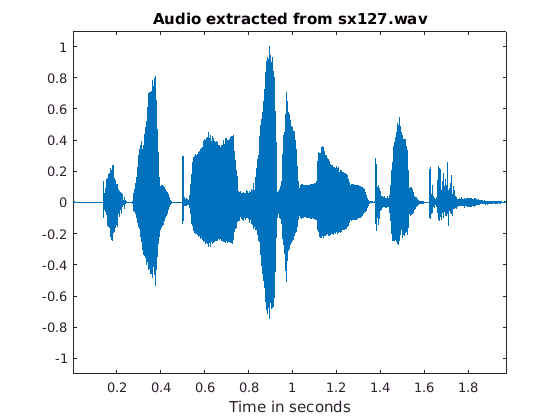

close all;
clearvars;
filename_audio = 'sx127.wav'; % Beware : NIST-formatted (sphere)
[audio_vect, fs] = audioread(filename_audio);
audio_vect = audio_vect/max(abs(audio_vect));
time_vect = (1:numel(audio_vect))/fs;
plot(time_vect, audio_vect);
xlabel('Time in seconds')
axis([time_vect(1), time_vect(end), -1.5, 1.5])
title(['Audio extracted from ', filename_audio]);

Displaying the samples corresponding to the woman saying the phoneme /p/ from 'temper' :

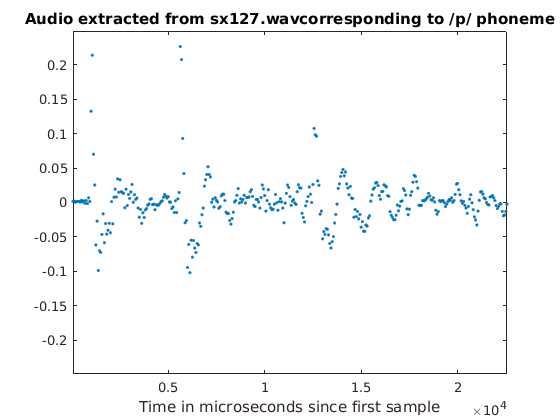

p = (26000:26360); % in samples
time_vect2 = 1e6*(1:numel(audio_vect(p)))/fs; % in microseconds
plot(time_vect2, audio_vect(p), '.');
max_value = max(abs(audio_vect(p))); %to align plot
axis([time_vect2(1), time_vect2(end), ...
    -1.1*max_value, 1.1*max_value])
xlabel('Time in microseconds since first sample')
title(['Audio extracted from ', filename_audio, 'corresponding to /p/ phoneme']);

This data is sampled at 

fs

fs = 16000

samples per seconds, and each sample is corresponding to the pressure on the microphone.

Often, there are some rapid changes, for example when producing a wovel, inducing a vibration i.e. a change of pressure, and sometime there's no changes (for example when not producing sound).

We only want to focus to the change of the pressure and producing an event asynchronously of a samplerate, in order to avoid redudant data, leveraging compression, robustness, etc. This is done with a level-crossing function, with a defined number of level to cross the signal with. The level crossing is done with linear interpolation, giving access to a stream of events corresponding to augmentation of the amplitude (ON events, polarity = 1), and diminution of the amplitude (OFF events, polarity = 0).

But what exactly is an event?

An event is the smallest brick of information transiting in the neural network. It can represent a spike and can be mathematically defined as ${\mathit{ev}}_i ={\left\lbrack t_i ,v_i ,p_i \right\rbrack }^T ,i\in Ν$, where ${\mathit{\text{ev}}}_i$ is the $i$th event and consists of a onr-dimensionnal level $v_i$, time $t_i$ and polarity $p_i$, where −1 and 1 respectively represents OFF and ON events, indicating that an increase or decrease in intensity level has been detected.

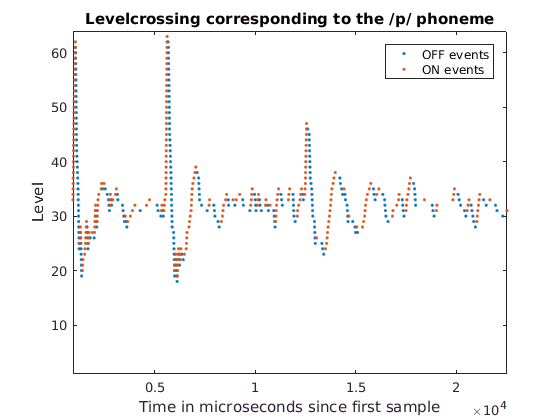

nb_levels = 64;
events = levelcrossing(audio_vect(p), fs, nb_levels);
plot(events.ts(events.p==0), events.level(events.p==0),'.'); hold on;
plot(events.ts(events.p==1), events.level(events.p==1),'.'); hold off;
legend({'OFF events', 'ON events'})
axis([events.ts(1), events.ts(end), 1, nb_levels])
title('Levelcrossing corresponding to the /p/ phoneme')
ylabel('Level')
xlabel('Time in microseconds since first sample')

So we have a stream of events. 

## Using the feature extractor, HoTS

Now, we want to extract the spatio-temporal features of the data corresponding to the sound recorded.

A layer of the model is built around basic principles :

1. The recent activity surrounding an event i in a time-surface is collected. This is an array of the most recent events for the levels in the neighborhhood centered at $v_i$

2. All the time-surfaces encontered in order to generate the time-surface prototypes of the learning base are clustered;

3. Then an assignment (descriptor) is made with the neareset prototype of each timed-event. The nature of the output of a layer is exactly the same as its input i.e. timed events, and we associate a descriptor based on its relative timings to recent activity in its spatial neighborhood. Thus, the same layer model with one layer output as input, can be used to create a Hierarchy of Time Surfaces (HoTS).

Features of the successive layers acquire more and more information, from bigger spatial receptive fields and from longer timescales. Each layer also automatically learns its own features from its predecessor’s output, removing the need for supervision, which only takes places in the classifier, some initial knowledge of the different classes are required while it is training.

To briefly summarize the algorithm, it takes events as input, and output them with new polarities : the nearest feature matching the time-surfaces assigned to them.

In this test, we will only do one layer of the model.

So we need to initialize the different variables and define the spatio-temporal limits of the extractor : 

-     $\tau$ defining the time of integration

-     $\xi$ and `nPow`, hyper-paramters of the clustering algorithm

-     `radius` of levels around the event (we extract what's happening at the ith event between  $v_i −\mathit{radius}$ and $v_i +\mathit{radius}$

-     The numbers of time-surface prototypes we want to extract

tau = 2000;
ksi = 1e-4;
nPow = 3;
radius = 5;
nbCenters = 4;

nbPols = numel(unique(events.p));
rng(381); % for reproducibility
centers = rand(nbCenters, nbPols, 2*radius+1);
lastEvents_framed = -inf(nbPols, nb_levels+2*radius);
dists = zeros(1,nbCenters);
occurancies = zeros(1,nbCenters);

We also initialized the spatio-temporal scene, where the last events for each level is set to -infinite, and the vector of distances of the event between each center. We can also count how many time the center will be activated.

This algorithm is an event-based, time-based, online algorithm. In order to reproduce this behaviour in MATLAB, we loop for each new events. We have one learning phase, computing the events, and one propagating phase, computing the new polarities for each events.

for learning = [true, false]
    for idx_ev = 1:numel(events.ts)
        ts = events.ts(idx_ev);
        p = events.p(idx_ev);
        level = events.level(idx_ev);

 Updates the spatio-temporal scene with the value of the last event

        lastEvents_framed(p+1, level+radius+1) = ts;

 Computes spatio-temporal context int the neighborhood of the event. We need an output centered at the current event, that's why the lastEvents_framed vector was initialized with 2*radius more levels, in order to avoid an "out of bounds" error in MATLAB.

        currCtx = ts-lastEvents_framed(:, level+1:level+2*radius+1);

Then, we apply a exponential kernel in the context. This way, the value at the center of the context is 1 (because it's the current event), and the value is decreasing exponentially depending on the time between the current event and the last events in the neighborhood.

        currCtx = exp(-currCtx/tau);

Next, distances are computed between the spatio-temporal context and each center. This is done with the Bhattacharyya distance, which isvery handy to compare vectors/matrices with, because the same matrices would have a distance of 0 and two de-correlated matrices towards infinity, avoiding outliers contribution, in this measurement method.

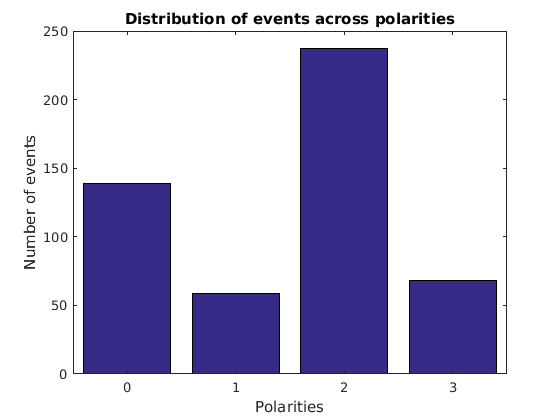

        for ind = 1:size(centers,1)

          dists(ind) = -log(sum((currCtx(:).*centers(ind,:)'))/numel(currCtx));
        end

We can find the index of the closest center (spatio-temporal protoype) by finding the minimum of distance for each centers.

        [~, nc] = min(dists);

We could analyse the distances in order to quantify the interest of what's happening at this event.

Finally, if we are learning, we want to update the centers. We used an online clustering algorithm.

        if learning
          coeff = ksi*((nPow+1)*dists(nc)^(nPow-1)+...
            nPow*dists(nc)^(nPow-2)*(sum(dists)-dists(nc)));
          centers(nc, :) = (1-coeff).*centers(nc,:)+coeff.*currCtx(:)';
          %% Manage bounds
          centers(nc, (centers(nc,:) < 0)) = 0;
          centers(nc, (centers(nc,:) > 1)) = 1;
        

Else, we are propagating the eents with a new polarity between 0 and nbCenters-1 affecting to nearest time-surface prototype calculated in the learning phase.

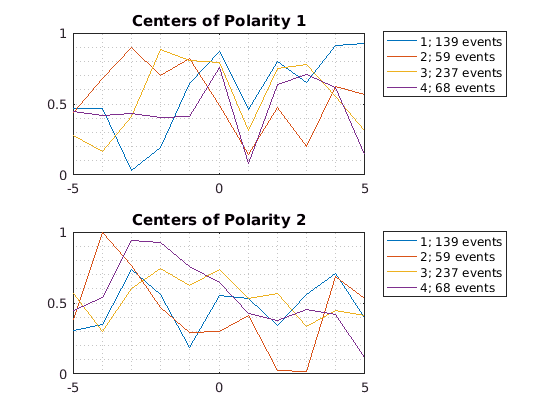

        else
          events.p(idx_ev) = nc-1;
          occurancies(nc) = occurancies(nc) + 1;
        end
    end

end

## Visualizing output stream

We can show the times when each center is activated for all the events.

bar((1:nbCenters)-1,occurancies)
xlabel('Polarities');
ylabel('Number of events');
title('Distribution of events across polarities');

Finally, we can visualize the centers and the new events, which contains more information, according to the centers computed. Sometimes the livescript is bugged, you should visualise 4 lines in each subplots correponding to the 4 centers (time-surface prototypes).

for ind_p = 1:nbPols
  legend_str = cell(1,nbCenters);
  subplot(nbPols, 1, ind_p)
  for ind_c = 1:nbCenters
    subCtx = centers(ind_c,ind_p,:);
    plot((-radius:radius),subCtx(:)); hold on;
    legend_str(ind_c) = {[num2str(ind_c), '; ', ... 
        num2str(occurancies(ind_c)),' events']};
  end
  legend(legend_str,'Location','bestoutside');
  grid minor;
  title(['Centers of Polarity ', num2str(ind_p)])
  axis([-radius radius 0 1]);
end
